# Examen RA3L - Matlab Partie 2 - Août 2025

% Nom :          ADDA                                   /10
% Prénom : SAB
% Matricule : 23027

Un accéléromètre a été placé sur un extincteur pour analyser le contenu fréquentiel des vibrations, lorsque celui-ci reçoit un petit choc. Le fichier 'Extincteur.mat' contient les données de temps `t1` et de tension `u1` en sortie du conditionnement du capteur. Ces données doivent cependant être prétraitées, car, outre la fréquence propre de l'extincteur ($\pm \;646\;\textrm{Hz}$) elles contiennent un offset et une composante parasite à 50 Hz.

**1) Charger les données. Déterminer la fréquence (**`Fs`**) et la période d'échantillonage (**`Ts`**) et éliminer l'offset présent dans le signal **`u1`**. Visualiser ensuite la tension **`u1_corr (après déduction de l'offset)`** en fonction du temps. ***( /1,5 point)*

clear all
close all
load extincteur.mat

%code
T=1/646;
ts=mode(diff(t1));
fs=1/ts;

u1_corr=u1-mean(u1);


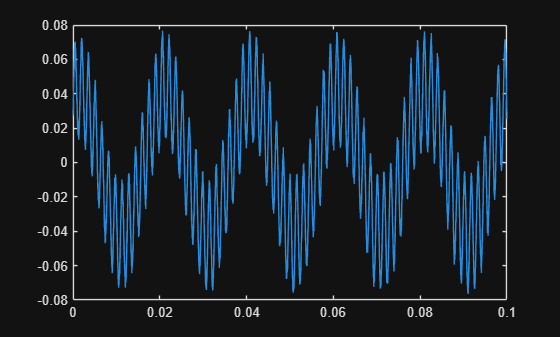

clf;
plot(t1,u1_corr)

Résultat attendu :

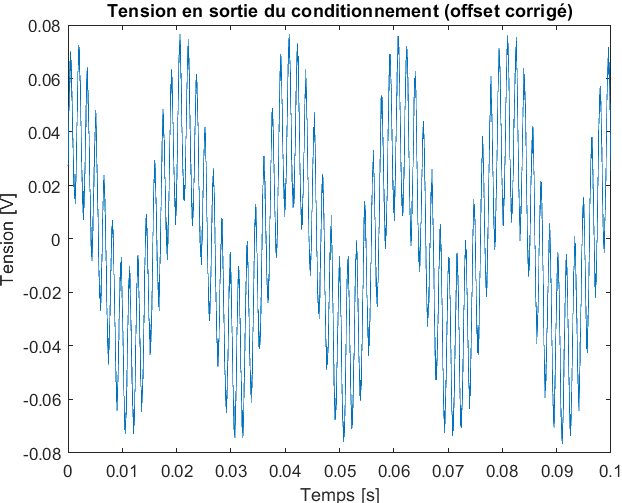

**2) Pour éliminer autant que possible la composante à 50 Hz, appliquer au signal **`u1_corr`** un filtre passe-haut dont la pulsation de coupure **$\omega_{c\;} =1000\;\frac{\textrm{rad}}{s}$** permet de réduire les fréquences inférieures à 159 Hz (**$f_{c\;} =\frac{\omega \;}{2\pi \;}\approx 159\;\textrm{Hz}$**) avec un coefficient d'amortissement **$\xi$ à 0,707 ($\left.\xi =0,707\right)$**. **


$$H\left(s\right)=\frac{\frac{s^2 }{\omega_c^2 }}{\left(\frac{s^2 }{\omega_c^2 \;}+\frac{2s\xi }{\omega {\;}_c }+1\right)}$$


**Afficher le signal de sortie **(à stocker dans la variable `u1_filt`)** et le signal d'entrée de ce filtre sur le même graphique. ***( /1 point)*

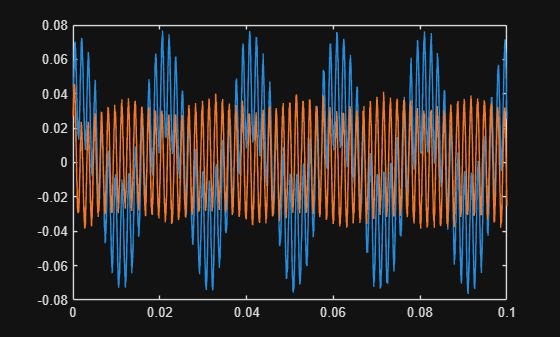

% code
wc=1000;
xi=0.707;
s=tf('s');
H=(s^2/wc^2)/((s^2/wc^2)+(2*s*xi/wc)+1);
u1_filt=lsim(H,u1_corr,t1);
plot(t1,u1_corr,t1,u1_filt)

Résultat attendu :

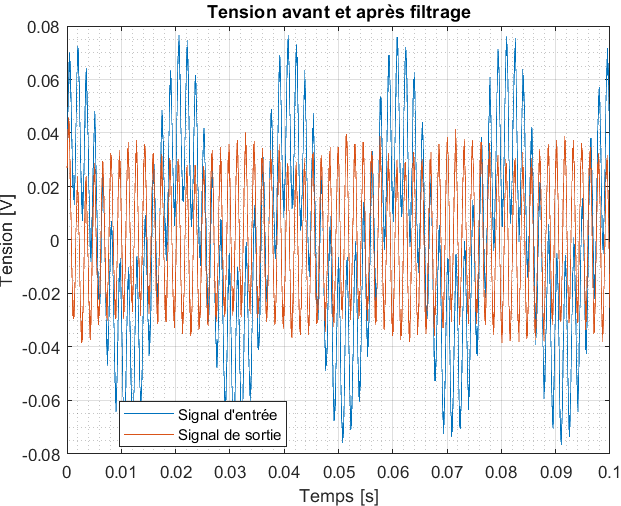

**3) Afficher la réponse indicielle et le diagramme de bode du filtre passe-haut et marquer d'un astérisque les points à 50 Hz et à 646 Hz. ***( /1 point)* 

**Sur feuille annexe, justifier : ***( /1 point)*

- **pourquoi la réponse indicielle tend asymptotiquement vers 0;**

- **à la lumière de ce diagramme de Bode, pourquoi une ondulation résiduelle à 50 Hz (déphasée par rapport à celle du signal original) est encore visible en sortie du filtre.**

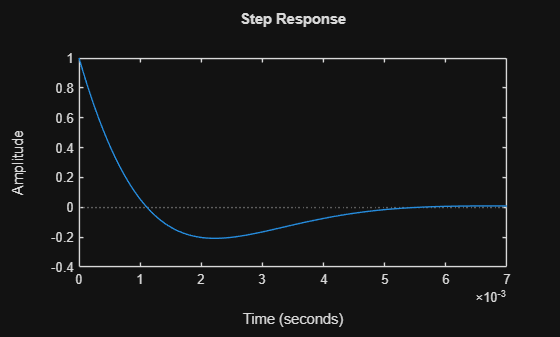

% code
clf;
step(H);

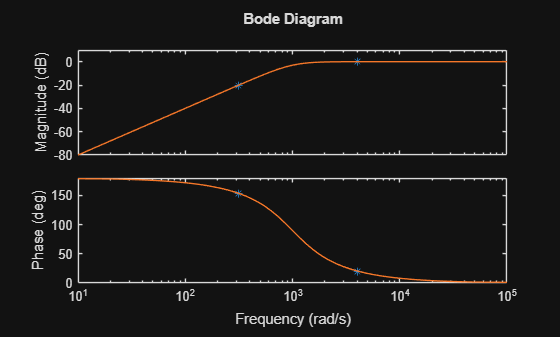

wspe=[50 646]*2*pi;
clf;
bode(H,wspe,'*')
hold on
bode(H)

Résultat attendu :

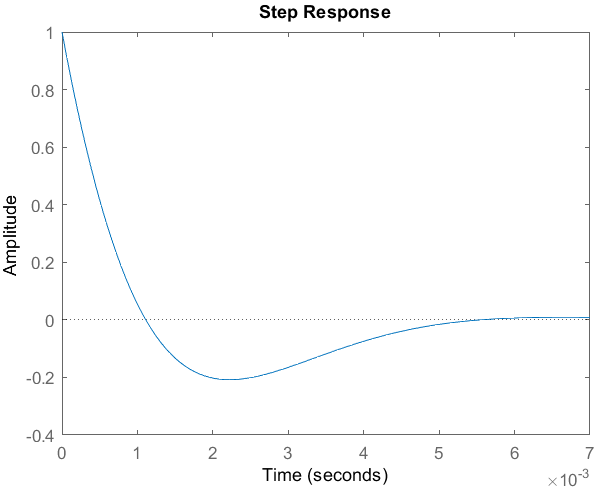

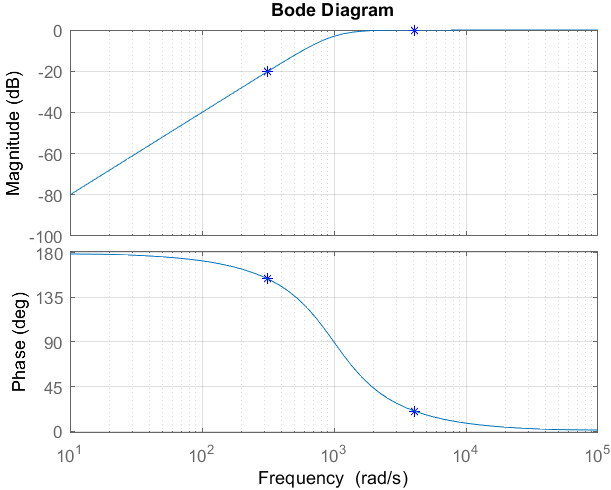

**4) Corriger le code permettant d'appliquer la FFT sur les signaux de tension (brut et après prétraitement)** **en justifiant chaque étape ****sur feuille annexe****. ***( /2 points)*

**Visualiser la FFT pour des fréquences allant de 0 à 2 kHz.*** ( /0,5 point)*

NB : Sans justification sur papier, le code ne rapportera aucun point. 

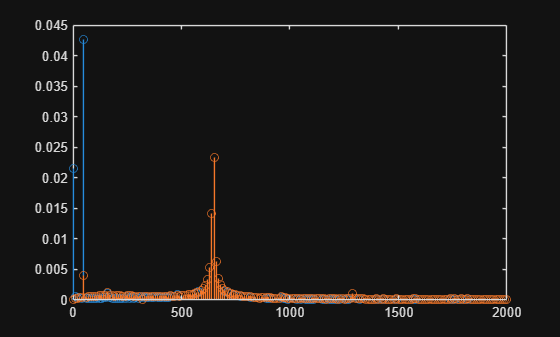

% code
N=length(u1);
X1=fft(u1);
X2=fft(u1_filt);

amp1=abs(X1)/N;
amp1=amp1(1:N/2+1);
amp1=amp1*2;
amp1(1)=amp1(1)/2;

amp2=abs(X2)/N;
amp2=amp2(1:N/2+1);
amp2=amp2*2;
amp2(1)=amp2(1)/2;

n=0:1:N/2;
df=fs/N;
f=n*df;
clf;
stem(f,amp1)
hold on 
stem(f,amp2)
axis([0 2000 0 0.045])

Résultat attendu : 

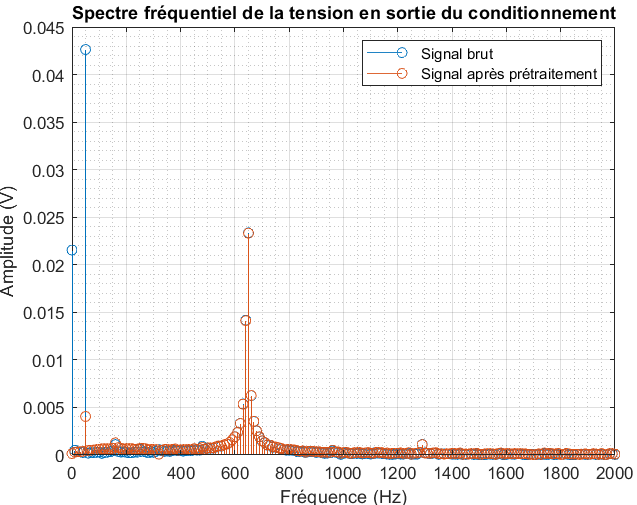

**5) Sur le résultat précédent, quel est le phénomène qui apparaît autour du pic à 646 Hz et qui n'apparaît pas autour de celui à 50 Hz ? Expliquer, avec du texte et/ou avec un/des schéma(s) sur feuille annexe, en quoi consiste ce phénomène et pourquoi il n'apparaît qu'autour du pic à 646 Hz. ***(    /2 points)*

**6) Supposant que la fréquence des vibrations mesurées vaut exactement 646 Hz, proposer une solution à apporter au code pour limiter drastiquement le phénomène abordé à la question 5 **(question ouverte : plusieurs solutions possibles)**.**

- **Expliquer brièvement la solution proposée sur feuille annexe ***( /0,5 point)*

- **Coder la solution proposée ci-dessous*** (0,5 point)*

% code